# Analisis matematico y diseño de control para QUBE Servo2 ( motor )

## Objetivo general

En este archivo *live vamos a desarrollar el anánlisis y procedimiento matematico para obtener correctamente el controlador de posición angular *$\theta$* y velocidad angular *$w$.

## *Objetivos especificos:*

- *Definir el modelo matematico que describe la dinamica de nuestra planta.*

- *Elegir el tiempo de muestreo.*

- *Pasar de continuo a discreto.*

- *Estudiar polos, estabilidad, controlabilidad y estados disponibles.*

- *Traducir especifiaciones temporales a polos deseados.*

- *Diseñar PID.*

- *Diseñar PP.*

- *Diseñar LQR.*

- *Evaluar experimentalmente.*

#### *Definimos nuestras ecuaciones:*

*Tengamos encuenta los parametros reales:*

- 
$$R=8.4\,\Omega
$$


- 
$$L=1.16\,mH$$


- 
$$K_t=0.04\,Nm\,/A$$


- 
$$K_e=0.042\,V\,sec\,/\,rad$$


- 
$$J=1.61 \times 10^{-5}\,kgm^2
$$


- 
$$V_{max}=\pm\,10\,V$$


- 
$$b=\,0.001$$


- 
$$T_s=0.001\,sec
$$


*Describimos nuestra planta con el siguiente diagrama:*

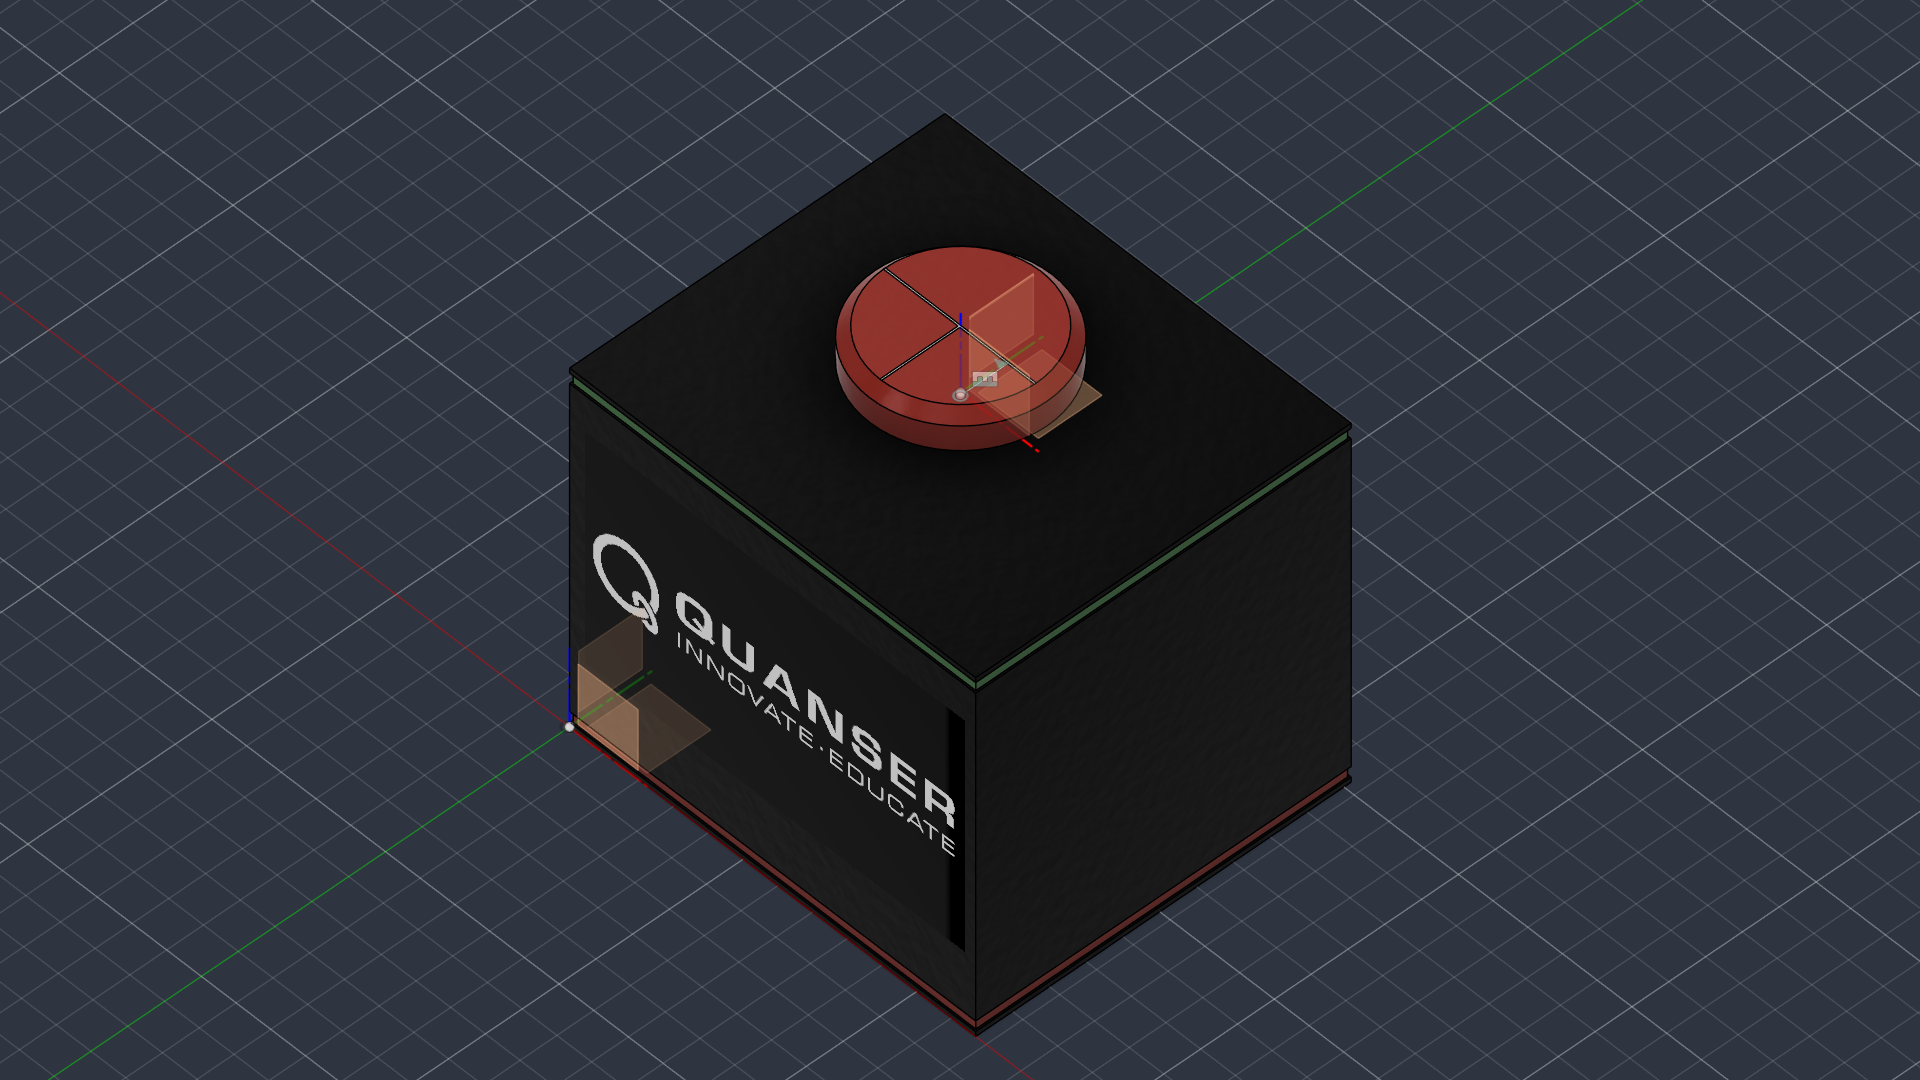              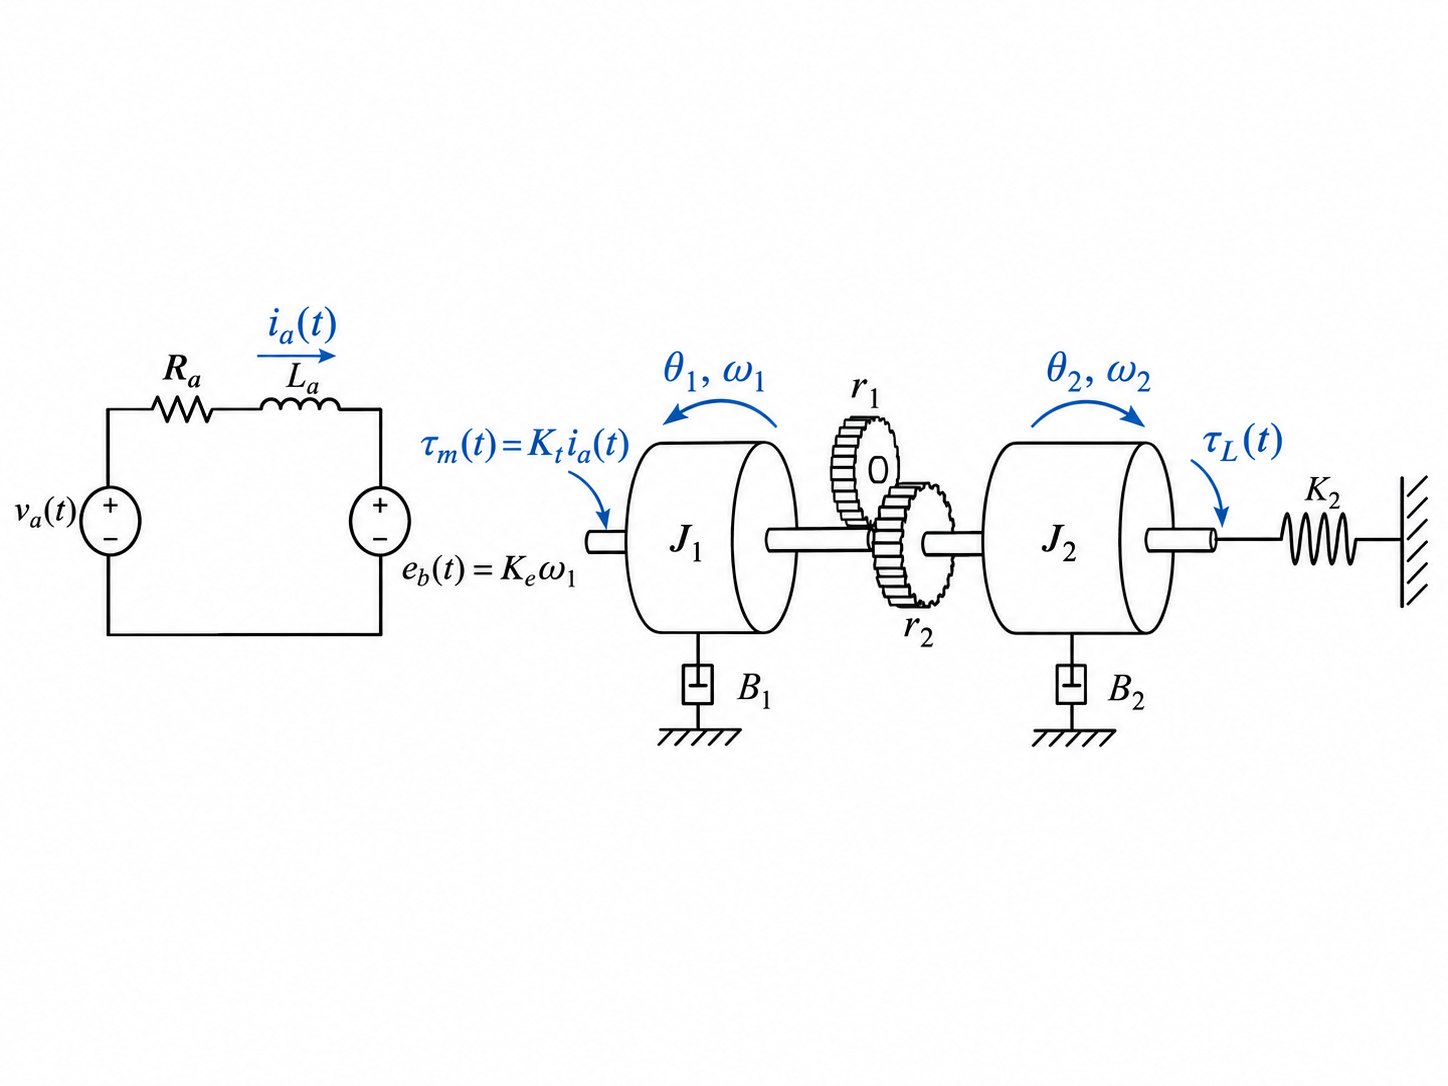

Del cual obtenemos:

- 
$$L\frac{dt}{dt}=V-R_i-K_e\,\omega $$


- 
$$J\frac{dw}{dt}=K_t\, i-b\, w$$


- 
$$\frac{d\theta}{dt}=\omega $$


#### Definimos nuestro tiempo de muestreo:

Para este caso en particular vamos a escoger de tiempo de muestreo como $T_s=0.001\,sec
$o $f_s=1000\,Hz$

#### Consideración:

Como temos que $\tau_e=1\,ms
$ y $\tau_e=\frac{L}{R}\approx1.38\times10^{-4}\,sec$, sabemos que tenemos $T_s\,\approx\,7.2\,\tau_e$. Por lo tanto podemos considerar:


$$L\frac{di}{dt}\approx0$$


Lo que nos da $i\,\approx\,\frac{V-K_e\,w}{R}$, y por lo tanto obtenemos las ecuaciones:

- 
$$\dot{w}\,=\,\frac{K_t}{JR}V-\frac{1}{J}\left(b+\frac{K_tK_e}{R}\right)w$$


- 
$$\dot{\theta}=\omega $$


Por lo tanto, tenemos:

Estados: $x = \left[ \matrix{ \,\theta\, \cr w } \right]$, Entrada: $u=V
$

Definimos nuestros coeficientes del espacio de estados:

syms s;
syms A B C D;
syms theta omega V;
syms R L Kt Ke J Vmax b Ts;

% Vector de estados y entrada
x = [theta; omega];
u = V;

% Matrices del espacio de estados
A = [ 0   1; 0  -(1/J)*(b + (Kt*Ke)/R) ];
disp(A);

$$\left(\begin{array}{cc} 0 & 1\\ 0 & -\frac{b+\frac{\mathrm{Ke}\,\mathrm{Kt}}{R}}{J} \end{array}\right)$$

B = [ 0; Kt/(J*R) ];
disp(B);

$$\left(\begin{array}{c} 0\\ \frac{\mathrm{Kt}}{J\,R} \end{array}\right)$$

C = [0 1];
disp(C);

     0     1



D = 0;
disp(D);

     0



Obtenemos la función de transferencia:

% Función de transferencia simbólica: G(s) = C*(sI - A)^-1*B + D
I = eye(size(A));
G_theta = C * inv(s*I - A) * B + D;
G_theta = simplify(G_theta);
disp(G_theta);

$$\frac{\mathrm{Kt}}{R\,b+\mathrm{Ke}\,\mathrm{Kt}+J\,R\,s}$$

Inicializamos parametros:

R_v    = 8.4;            % Ohm
L_v    = 1.16e-3;        % H  (1.16 mH)
Kt_v   = 0.04;           % N*m/A
Ke_v   = 0.042;          % V*s/rad
J_v    = 1.61e-5;        % kg*m^2
Vmax   = 10;             % V
b_v    = 0.001;
Ts_v   = 0.001;          % s

Volvemos a calcular:

vals  = {R_v, Kt_v, Ke_v, J_v, b_v};
symbs = {R, Kt, Ke, J, b};

% Sustituimos en la FT simbolica
G_omega_n = subs(G_theta, symbs, vals);

% Reducir la expresion
G_omega_n = simplify(G_omega_n);

% Ver la expresion con valores ya reemplazados
pretty(vpa(G_omega_n, 5));   % 5 dígitos significativos

        2.196e+20
------------------------
7.4248e+17 s + 5.534e+19



Lo dejamos en forma estandar:

% Extraer numerador y denominador
[num, den] = numden(G_omega_n);
num = sym2poly(num);
den = sym2poly(den);

% Construir la funcion de transferencia
G = tf(num, den)


G =
 
        4.612e21
  ---------------------
  1.559e19 s + 1.162e21
 
Continuous-time transfer function.



% Simplificar (cancelar polos/ceros comunes)
G = minreal(G)


G =
 
    295.8
  ---------
  s + 74.53
 
Continuous-time transfer function.


*Vemos respuesta paso y sus caracteristicas:*

%% Respuesta a un escalón físico de voltaje

V_step = 1.0;        % V
t_final = 1.0;       % s

t = 0:Ts_v:t_final;

[y, t] = step(V_step * G, t);

S = stepinfo(y, t);

disp('Respuesta a escalón de voltaje:');

Respuesta a escalón de voltaje:


disp(['Voltaje aplicado: ', num2str(V_step), ' V']);

Voltaje aplicado: 1 V


disp(['Velocidad final aproximada: ', num2str(y(end)), ' rad/s']);

Velocidad final aproximada: 3.9683 rad/s


disp(dcgain(G));

    3.9683



disp(S);

         RiseTime: 0.0295
    TransientTime: 0.0525
     SettlingTime: 0.0525
      SettlingMin: 3.5746
      SettlingMax: 3.9683
        Overshoot: 0
       Undershoot: 0
             Peak: 3.9683
         PeakTime: 0.4640



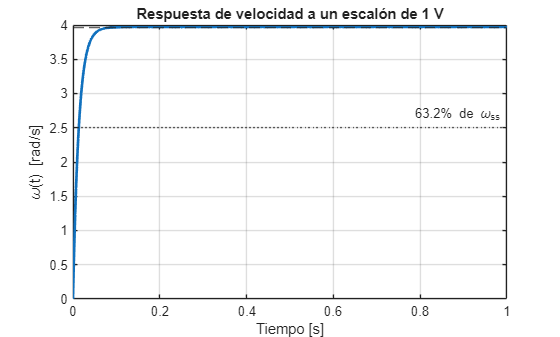


figure;

plot(t, y, 'LineWidth', 2);
grid on;
box on;

xlabel('Tiempo [s]');
ylabel('\omega(t) [rad/s]');

title('Respuesta de velocidad a un escalón de 1 V');
omega_ss = dcgain(G) * V_step;

yline(omega_ss, '--', ...
    sprintf('\\omega_{ss} = %.2f rad/s', omega_ss));

yline(0.632 * omega_ss, ':', ...
    '63.2% de \omega_{ss}');

Vemos diagrama polo cero:

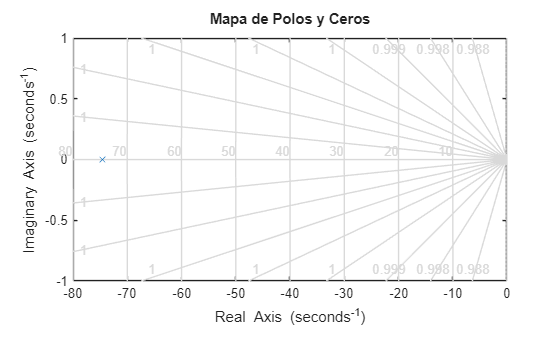

% 5. Generar el mapa de polos y ceros
figure; % Abre una nueva ventana de figura
pzmap(G);
grid on;
title('Mapa de Polos y Ceros');


% 6. Obtener los valores numéricos de los polos y ceros (opcional)
[p, z] = pzmap(G);
disp('Polos del sistema (p):');

Polos del sistema (p):


disp(p);

  -74.5342



disp('Ceros del sistema (z):');

Ceros del sistema (z):


disp(z);

### Diseño de controladores

Antes de pasar con el diseño del control con PID, hacemos una pequeña reducción del diagrama de estados dependiendo del tipo de control que queremos hacer ( posición / velocidad ). Por lo que el modelo de posición y velocidad, nos quedaria de la forma:

%% Modelo numerico en espacio de estados

% Sustituimos los parametros fisicos en A y B
A_n = double(subs(A, symbs, vals));
B_n = double(subs(B, symbs, vals));

% Matrices de salida
C_omega = [0 1];
C_theta = [1 0];

D_n = 0;

disp('Matriz A numerica:');

Matriz A numerica:


disp(A_n);

         0    1.0000
         0  -74.5342




disp('Matriz B numerica:');

Matriz B numerica:


disp(B_n);

         0
  295.7705



Ahora construimos dos vistas de la misma planta:

%% Planta continua observada desde velocidad y posicion

sys_omega_c = ss(A_n, B_n, C_omega, D_n);
sys_theta_c = ss(A_n, B_n, C_theta, D_n);

G_omega = minreal(tf(sys_omega_c));
G_theta = minreal(tf(sys_theta_c));

disp('Funcion de transferencia de velocidad:');

Funcion de transferencia de velocidad:


G_omega


G_omega =
 
    295.8
  ---------
  s + 74.53
 
Continuous-time transfer function.



disp('Funcion de transferencia de posicion:');

Funcion de transferencia de posicion:


G_theta


G_theta =
 
      295.8
  -------------
  s^2 + 74.53 s
 
Continuous-time transfer function.


Discretizamos nuestros modelos con ZOH:

% Planta completa: salida = [theta, omega]
C_full = eye(2);
D_full = zeros(2,1);

sys_full_c = ss(A_n, B_n, C_full, D_full);

% Discretizacion mediante Zero-Order Hold
sys_full_d = c2d(sys_full_c, Ts_v, 'zoh');

Ad = sys_full_d.A;
Bd = sys_full_d.B;

disp('Matriz Ad:');

Matriz Ad:


disp(Ad);

    1.0000    0.0010
         0    0.9282




disp('Matriz Bd:');

Matriz Bd:


disp(Bd);

    0.0001
    0.2850



Y discretizamos las dos funciones:

%% Funciones de transferencia discretas

G_omega_d = c2d(G_omega, Ts_v, 'zoh');
G_theta_d = c2d(G_theta, Ts_v, 'zoh');

disp('Planta discreta de velocidad:');

Planta discreta de velocidad:


G_omega_d


G_omega_d =
 
    0.285
  ----------
  z - 0.9282
 
Sample time: 0.001 seconds
Discrete-time transfer function.



disp('Planta discreta de posicion:');

Planta discreta de posicion:


G_theta_d


G_theta_d =
 
  0.0001443 z + 0.0001407
  -----------------------
  z^2 - 1.928 z + 0.9282
 
Sample time: 0.001 seconds
Discrete-time transfer function.


### Revisamos controlabilidad y observabilidad:

%% Controlabilidad
Co = ctrb(Ad, Bd);

rank_Co = rank(Co);

disp('Matriz de controlabilidad:');

Matriz de controlabilidad:


disp(Co);

    0.0001    0.0004
    0.2850    0.2645




fprintf('Rango de controlabilidad: %d\n', rank_Co);

Rango de controlabilidad: 2


fprintf('Numero de estados: %d\n', size(Ad,1));

Numero de estados: 2



%% Observabilidad desde posicion y velocidad
Ob_theta = obsv(Ad, C_theta);
Ob_omega = obsv(Ad, C_omega);

rank_Ob_theta = rank(Ob_theta);
rank_Ob_omega = rank(Ob_omega);

fprintf('Observabilidad desde posicion: %d\n', rank_Ob_theta);

Observabilidad desde posicion: 2



fprintf('Observabilidad desde velocidad: %d\n', rank_Ob_omega);

Observabilidad desde velocidad: 1


### 1. Diseño del control con PID

#### Empezamos con PID de velocidad

%% PID digital de velocidad
[C_PID_omega, info_PID_omega] = pidtune(G_omega_d, 'PIDF');

disp('Controlador PID de velocidad:');

Controlador PID de velocidad:


C_PID_omega


C_PID_omega =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 0.394, Ki = 50.9, Kd = -2.36e-05, Tf = 0.000564, Ts = 0.001
 
Sample time: 0.001 seconds
Discrete-time PIDF controller in parallel form.



disp('Informacion de sintonizacion:');

Informacion de sintonizacion:


disp(info_PID_omega);

                Stable: 1
    CrossoverFrequency: 136.6191
           PhaseMargin: 69.1514



Cerramos el lazo:

%% Lazo cerrado PID de velocidad
T_PID_omega = feedback( C_PID_omega * G_omega_d, 1);

Probamos:

omega_ref = 5;      % rad/s
t_control = 0:Ts_v:1;

[y_PID_omega, t_control] = ...
    step(omega_ref * T_PID_omega, t_control);

### 2. Pole Placement de velocidad

%% Modelo minimo de velocidad

A_omega = A_n(2,2);
B_omega = B_n(2);
C_omega_min = 1;
D_omega_min = 0;

sys_omega_min_c = ss( ...
    A_omega, ...
    B_omega, ...
    C_omega_min, ...
    D_omega_min);

sys_omega_min_d = ...
    c2d(sys_omega_min_c, Ts_v, 'zoh');

Ad_omega = sys_omega_min_d.A;
Bd_omega = sys_omega_min_d.B;

Especificamos temporalmente:

%% Especificacion temporal para velocidad

Tsettle_des_omega = ...
    0.5 * S.SettlingTime;

fprintf( ...
    'Settling deseado: %.4f s\n', ...
    Tsettle_des_omega);

Settling deseado: 0.0262 s



p_omega_s = ...
    -4 / Tsettle_des_omega;

p_omega_z = ...
    exp(p_omega_s * Ts_v);

fprintf( ...
    'Polo continuo deseado: %.4f\n', ...
    p_omega_s);

Polo continuo deseado: -152.3937



fprintf( ...
    'Polo discreto deseado: %.6f\n', ...
    p_omega_z);

Polo discreto deseado: 0.858650


Calculamos la ganancia:

K_PP_omega = ...
    place(Ad_omega, ...
          Bd_omega, ...
          p_omega_z);

disp('K Pole Placement velocidad:');

K Pole Placement velocidad:


disp(K_PP_omega);

    0.2439




Acl_PP_omega = ...
    Ad_omega - ...
    Bd_omega*K_PP_omega;

N_PP_omega = 1 / ...
    (C_omega_min * ...
    ((1 - Acl_PP_omega) \ Bd_omega));

Construimos el sistema:

T_PP_omega = ss( ...
    Acl_PP_omega, ...
    Bd_omega*N_PP_omega, ...
    C_omega_min, ...
    0, ...
    Ts_v);

Simulamos:

[y_PP_omega, ~] = ...
    step(omega_ref * ...
         T_PP_omega, ...
         t_control);

### 3. Ahora LQR de velocidad

%% LQR velocidad

omega_max_design = 5;  % rad/s
V_design = Vmax;       % V

Q_LQR_omega = ...
    1/(omega_max_design^2);

rho_omega = 1;

R_LQR_omega = ...
    rho_omega/(V_design^2);

[K_LQR_omega, ...
 P_LQR_omega, ...
 poles_LQR_omega] = ...
    dlqr(Ad_omega, ...
         Bd_omega, ...
         Q_LQR_omega, ...
         R_LQR_omega);

disp('K LQR velocidad:');

K LQR velocidad:


disp(K_LQR_omega);

    1.3075




disp('Polos LQR velocidad:');

Polos LQR velocidad:


disp(poles_LQR_omega);

    0.5555



Precompensador:

Acl_LQR_omega = ...
    Ad_omega - ...
    Bd_omega*K_LQR_omega;

N_LQR_omega = 1 / ...
    (C_omega_min * ...
    ((1 - Acl_LQR_omega) \ Bd_omega));

T_LQR_omega = ss( ...
    Acl_LQR_omega, ...
    Bd_omega*N_LQR_omega, ...
    C_omega_min, ...
    0, ...
    Ts_v);

[y_LQR_omega, ~] = ...
    step(omega_ref * ...
         T_LQR_omega, ...
         t_control);

Comparamos todos los controladores de velocidad:

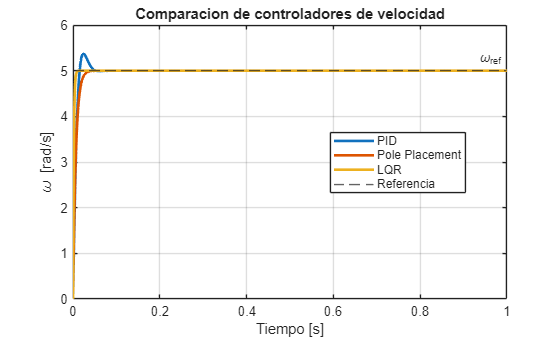

%% Comparacion de controladores de velocidad

figure;

plot(t_control, ...
    y_PID_omega, ...
    'LineWidth', 2);

hold on;

plot(t_control, ...
    y_PP_omega, ...
    'LineWidth', 2);

plot(t_control, ...
    y_LQR_omega, ...
    'LineWidth', 2);

yline(omega_ref, '--', ...
    '\omega_{ref}');

grid on;
box on;

xlabel('Tiempo [s]');
ylabel('\omega [rad/s]');

title('Comparacion de controladores de velocidad');

legend( ...
    'PID', ...
    'Pole Placement', ...
    'LQR', ...
    'Referencia', ...
    'Location', 'best');

## Ahora hacemos control de posición:

### 1. PID de posición:

%% PID digital de posicion

[C_PID_theta, info_PID_theta] = ...
    pidtune(G_theta_d, 'PIDF');

disp('PID posicion:');

PID posicion:


C_PID_theta


C_PID_theta =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 50.3, Ki = 591, Kd = 0.392, Tf = 0.000565, Ts = 0.001
 
Sample time: 0.001 seconds
Discrete-time PIDF controller in parallel form.



T_PID_theta = feedback( ...
    C_PID_theta * G_theta_d, ...
    1);

theta_ref = pi/2;     % 90 grados
t_position = 0:Ts_v:1;

[y_PID_theta, t_position] = ...
    step(theta_ref * ...
         T_PID_theta, ...
         t_position);

U_PID_theta = ...
    feedback( ...
        C_PID_theta, ...
        G_theta_d);

r_theta = ...
    theta_ref * ...
    ones(size(t_position));

u_PID_theta = ...
    lsim(U_PID_theta, ...
         r_theta, ...
         t_position);

### 2. Pole placement posición:

%% Especificaciones Pole Placement posicion

Mp_des = 0.05;        % 5 % overshoot
Tsettle_des = 0.20;   % s

zeta = ...
    -log(Mp_des) / ...
    sqrt(pi^2 + log(Mp_des)^2);

wn = ...
    4 / ...
    (zeta*Tsettle_des);

p1_s = ...
    -zeta*wn + ...
    1j*wn*sqrt(1-zeta^2);

p2_s = conj(p1_s);

poles_theta_z = ...
    exp([p1_s p2_s]*Ts_v);

disp('Polos discretos deseados:');

Polos discretos deseados:


disp(poles_theta_z);

   0.9800 + 0.0206i   0.9800 - 0.0206i




K_PP_theta = ...
    place(Ad, ...
          Bd, ...
          poles_theta_z);

disp('K Pole Placement posicion:');

K Pole Placement posicion:


disp(K_PP_theta);

    2.8885   -0.1130



Precompensador de posición:

Acl_PP_theta = ...
    Ad - Bd*K_PP_theta;

N_PP_theta = 1 / ...
    (C_theta * ...
    ((eye(2) - Acl_PP_theta) \ Bd));

T_PP_theta = ss( ...
    Acl_PP_theta, ...
    Bd*N_PP_theta, ...
    C_theta, ...
    0, ...
    Ts_v);

[y_PP_theta, ~] = ...
    step(theta_ref * ...
         T_PP_theta, ...
         t_position);

### 3. LQR de posición:

theta_max_design = deg2rad(10);
omega_max_design = 10;

Q_LQR_theta = diag([ ...
    1/(theta_max_design^2), ...
    1/(omega_max_design^2) ...
]);

rho_theta = 1;

R_LQR_theta = ...
    rho_theta/(Vmax^2);

[K_LQR_theta, ...
 P_LQR_theta, ...
 poles_LQR_theta] = ...
    dlqr(Ad, ...
         Bd, ...
         Q_LQR_theta, ...
         R_LQR_theta);

disp('K LQR posicion:');

K LQR posicion:


disp(K_LQR_theta);

   49.7959    0.8213




disp('Polos LQR posicion:');

Polos LQR posicion:


disp(poles_LQR_theta);

    0.9450
    0.7419




Acl_LQR_theta = ...
    Ad - Bd*K_LQR_theta;

N_LQR_theta = 1 / ...
    (C_theta * ...
    ((eye(2) - Acl_LQR_theta) \ Bd));

T_LQR_theta = ss( ...
    Acl_LQR_theta, ...
    Bd*N_LQR_theta, ...
    C_theta, ...
    0, ...
    Ts_v);

[y_LQR_theta, ~] = ...
    step(theta_ref * ...
         T_LQR_theta, ...
         t_position);

Realizamos comparación para los controladores de posición:

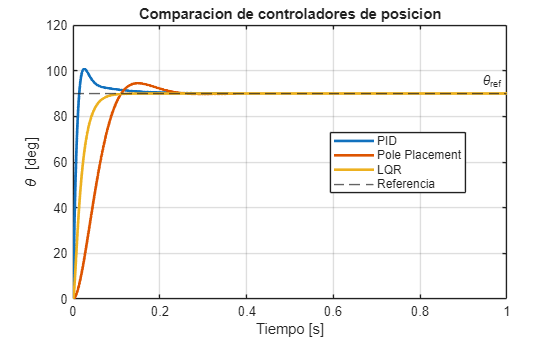

%% Comparacion de controladores de posicion

figure;

plot(t_position, ...
    rad2deg(y_PID_theta), ...
    'LineWidth', 2);

hold on;

plot(t_position, ...
    rad2deg(y_PP_theta), ...
    'LineWidth', 2);

plot(t_position, ...
    rad2deg(y_LQR_theta), ...
    'LineWidth', 2);

yline(rad2deg(theta_ref), ...
    '--', ...
    '\theta_{ref}');

grid on;
box on;

xlabel('Tiempo [s]');
ylabel('\theta [deg]');

title('Comparacion de controladores de posicion');

legend( ...
    'PID', ...
    'Pole Placement', ...
    'LQR', ...
    'Referencia', ...
    'Location', 'best');